# Progetto Finale- Early Warning Systems

#### Fintech course, business cases part - Raffaele Zenti

Gruppo 

- Bakir Rajaa (id 10616168)

- Basilico Margherita (id 10568924)

- Cacciatori Carlotta (id 10660287)

- Cinciripini Tiziano (id 10692521)

- Lepore Marco (id 10652158)

## The business case description

Market crises correspond to "risk-off" situations, in which risk premia and financial assets exhibit anomalous behaviour. We want to recognize these situations using data science. 

#### The dataset

The dataset consists in weekly data from Bloomberg containing

- Key equity indices 

- Bond indices (Global, Corporate  IG/HY, Inflation-linked, Municipals,  Mortgages) 

- Short/medium/long term interest  rates 

- Key exchange rates 

- Commodities 

- Leading indicators (Economic  surprise, Baltic Dry Index) 

- VIX (option implied volatility)

- a label that indicates if the situation is normal (0) or abnormal (1)

## Our approach 

### First we wanted to inspect the dataset in order to see if it was clean and balanced

The dataset is made up of 1111 observations among which 874 are classified as normal and 237 as abnormal. We may reason in term of balancing the classes in order to improve our classifier, but in the end we did not cancel some of the normal situations or add any "fake" abnormal observation. We have decided to not clean the dataset: we would not have precisely known if the removed observations were simply outliers or real crises. In fact we reckon that it does not make sense to clean the dataset if what we are looking for are anomalies.

close all
clc
%load the data
load('C:\Users\margh\Documents\II anno\Fintech\Zenti\Business3\EWS.mat')
%load("EWS.mat")

nNormal = sum(Y==0)

nNormal = 874

nAbnormal = sum(Y==1)

nAbnormal = 237

For now we collect the entire dataset in a unique matrix:

DataNS = [BDIY Cl1 CRY DXY ECSURPUS EMUSTRUU EONIA GBP GT10 GTDEM30Y...
       GTDEM2Y GTDEM10Y GTGBP30Y GTGBP2Y GTGBP20Y GTITL30YR...
       GTITL2YR GTITL10YR GTJPY30YR GTJPY2YR GTJPY10YR JPY LF94TRUU ...
       LF98TRUU LG30TRUU LMBITR LP01TREU LUACTRUU LUMSTRUU MXBR MXCN...
       MXEU MXIN MXJP MXRU MXUS US0001M USGG30YR USGG2YR USGG3M...
       VIX XAUBGNL];
DataNSY = [DataNS Y];

## **Feature selection**

We asked ourselves: "Are ALL of these 42 features really significant in detecting risk-off situations?". We then did not really select the features, but we used these informations for building a classifier that was based on some tresholds in some of the features.

### PCA

First of all we have tried PCA with raw data and with scaled data because of the different scales of the features.

[coeff,score,latent,tsquared,explained,mu] = pca(DataNS);
explained;

[coeff,score,latent,tsquared,explained,mu] = pca(rescale(DataNS));
explained

explained =    62.2664
   27.3953
    8.6827
    0.9641
    0.2804
    0.2435
    0.0656
    0.0499
    0.0248
    0.0112


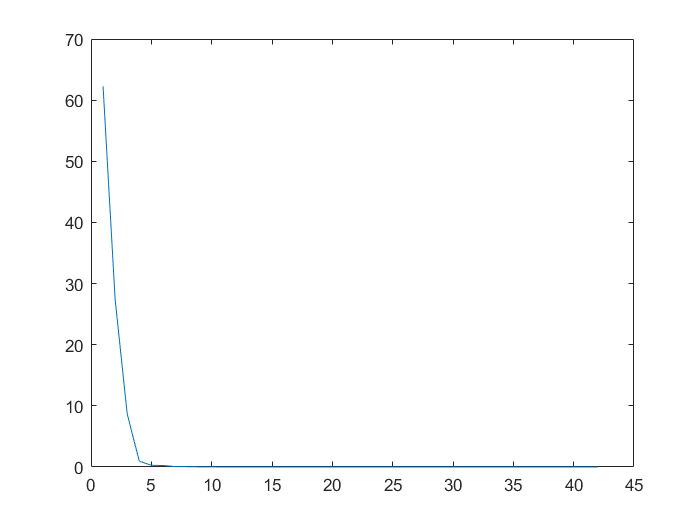

plot(explained)

We could reduce the number of features from 42 to the first three or four, in which we have the elbow, components which alone explaine more than 98% of variability. We try to plot the three vectors of scores to find out whether the PCA can be helpful for the classification, so if we can visualize noticeable groups.

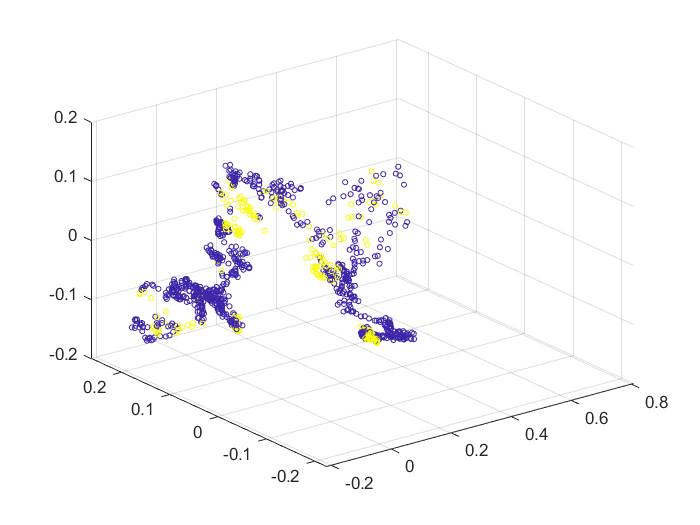

figure
scatter3(score(:,1),score(:,2),score(:,3),10,Y)

We can't identify evident groups so we have decided to discard this approach for feature selection.

Then we tried to do PCA with the same dataset constructed in the Matlab live script: considering the differences or the log differences (in the case the variables were all positive) or the features themselves when they were already stationary. 

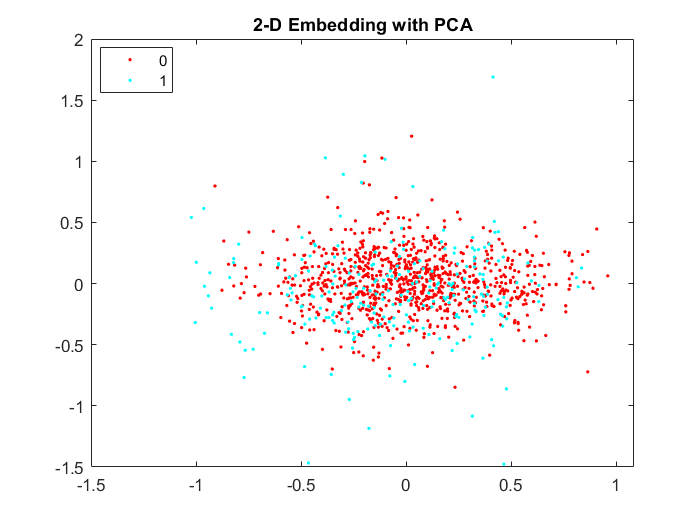

%% from Zenti code
% % Always positive variables => log-differences (log-returns)
Indices_Currencies = [XAUBGNL BDIY CRY Cl1 DXY EMUSTRUU GBP JPY LF94TRUU LF98TRUU LG30TRUU LMBITR LP01TREU...
       LUACTRUU LUMSTRUU MXBR MXCN MXEU MXIN MXJP MXRU MXUS VIX];

% Possibly negative variables => first differences
InterestRates = [EONIA GTDEM10Y GTDEM2Y GTDEM30Y GTGBP20Y GTGBP2Y GTGBP30Y...
    GTITL10YR GTITL2YR GTITL30YR GTJPY10YR GTJPY2YR GTJPY30YR US0001M USGG3M USGG2YR GT10 USGG30YR];

Data = [diff(log(Indices_Currencies)) ECSURPUS(2:end) diff(InterestRates)]; % make stationary
Response = Y(2:end); % we lose one observation (the first)
%% end of Zenti code

% PCA without rescaling the variables
[coeff,score,latent] = pca(Data);
figure
gscatter(score(:,1),score(:,2), Response)
title('2-D Embedding with PCA')

As we can see, the first two principal components do not give any information about the type of the observation. In red we have the normal observations, in blue the anomalous ones. It seems that the blue dots are more towards the periphery of the sort of ellypsis and more on the bottom/left part but the results are not so evident.

V1=cov(Data);
[coeff, latent, explained]=pcacov(V1);
explained

explained =    32.1536
   20.0437
   14.2337
    6.5407
    4.8611
    3.6354
    2.3948
    2.1701
    1.9826
    1.8806


Moreover, the explained variance is high even until about 15 components. We see an elbow in the explained percentage of variance at about 7 principal components, but if we look at the scores we cannot explain well what the first principal components represent.

score

score =     0.0112    0.3434   -0.1623    0.1434    0.1128   -0.1356   -0.0525    0.0533   -0.0075    0.0311   -0.0176    0.0770    0.0030    0.1068    0.0667    0.0373    0.0383   -0.0132   -0.0220    0.0457    0.0467   -0.0235   -0.0480    0.0410   -0.0087    0.0075   -0.0101   -0.0010    0.0176   -0.0020   -0.0075   -0.0010    0.0039   -0.0152   -0.0009    0.0090   -0.0107    0.0070    0.0020    0.0041   -0.0004    0.0004
    0.1034   -0.3036    0.1305    0.1305   -0.1257    0.1836    0.0478   -0.0592    0.0222    0.0044   -0.1074    0.1915   -0.0777   -0.0228   -0.0032    0.0067   -0.0751   -0.0006   -0.0252   -0.0460    0.0025    0.0286   -0.0125    0.0352   -0.0041    0.0221   -0.0013   -0.0069   -0.0047   -0.0255    0.0085    0.0021    0.0292   -0.0000   -0.0022   -0.0066   -0.0059    0.0021   -0.0065    0.0034    0.0034    0.0003
    0.1654   -0.1161    0.1108    0.1814   -0.1906    0.2001    0.0094    0.0487   -0.0734   -0.1106    0.0861   -0.1105   -0.0496   -0.0462    0.1146

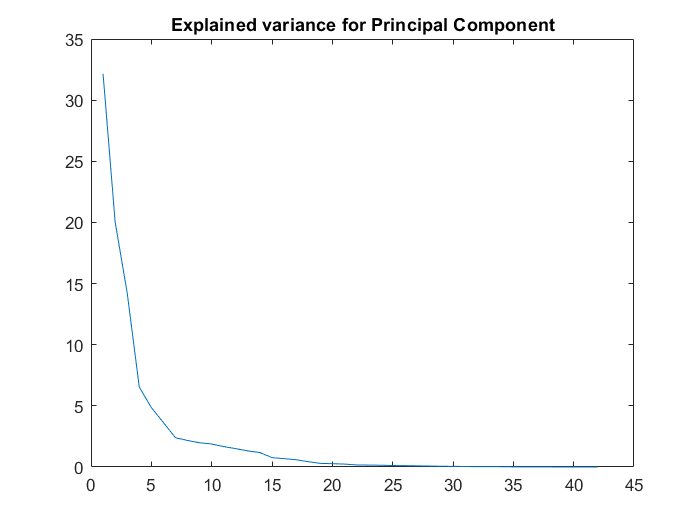

plot(explained)
title('Explained variance for Principal Component')

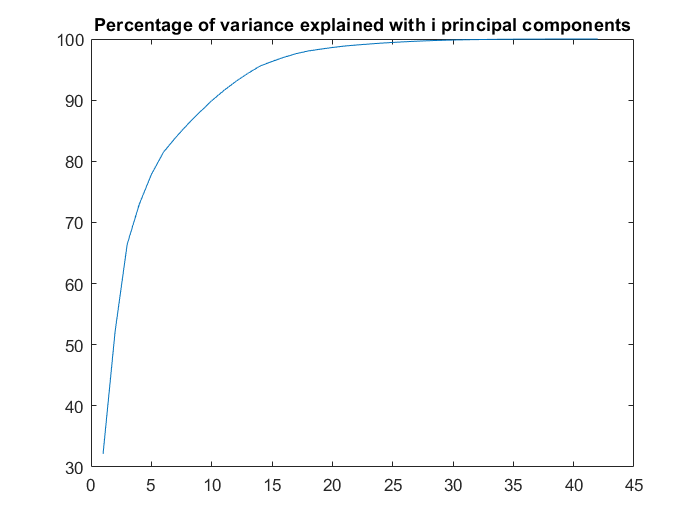

partialSum = zeros(42, 1);
partialSum(1) = explained(1);
for i = 2:42
partialSum(i) = partialSum(i-1) + explained(i);
end
plot(partialSum)
title('Percentage of variance explained with i principal components')

We did the same with the dataset rescaled, so that we did not have problems of different orders of magnitude.

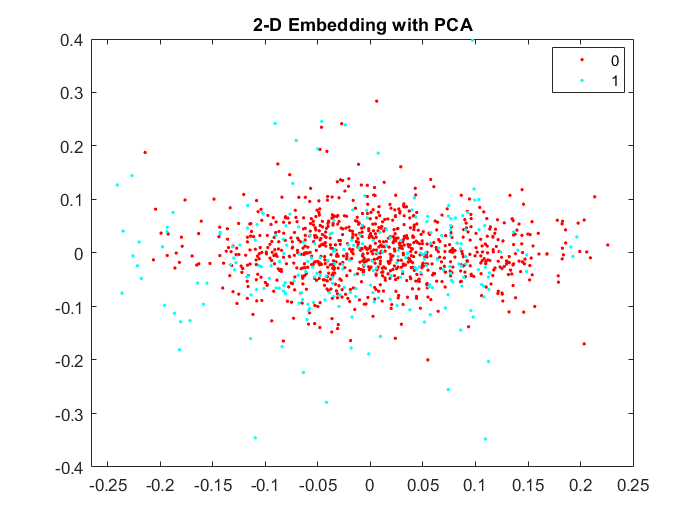

%PCA with rescaling the variables
[coeff2,score2,latent2] = pca(rescale(Data));
figure
gscatter(score2(:,1),score2(:,2), Response)
title('2-D Embedding with PCA')

Again, the blue dots (anomalies) seem to stay more at the periphery and more on the bottom/left part of the graph, but they largely overlap with the red dots (normal situations).

V2=cov((rescale(Data)));
[coeff2, latent2, explained2]=pcacov(V2);
explained2

explained2 =    32.1536
   20.0437
   14.2337
    6.5407
    4.8611
    3.6354
    2.3948
    2.1701
    1.9826
    1.8806


score2

score2 =     0.0026    0.0809   -0.0382    0.0338    0.0266   -0.0319   -0.0124    0.0126   -0.0018    0.0073   -0.0041    0.0181    0.0007    0.0252    0.0157    0.0088    0.0090   -0.0031   -0.0052    0.0108    0.0110   -0.0055   -0.0113    0.0097   -0.0020    0.0018   -0.0024   -0.0002    0.0041   -0.0005   -0.0018   -0.0002    0.0009   -0.0036   -0.0002    0.0021   -0.0025    0.0017    0.0005    0.0010   -0.0001    0.0001
    0.0243   -0.0715    0.0307    0.0307   -0.0296    0.0432    0.0113   -0.0140    0.0052    0.0010   -0.0253    0.0451   -0.0183   -0.0054   -0.0008    0.0016   -0.0177   -0.0001   -0.0059   -0.0108    0.0006    0.0067   -0.0029    0.0083   -0.0010    0.0052   -0.0003   -0.0016   -0.0011   -0.0060    0.0020    0.0005    0.0069   -0.0000   -0.0005   -0.0015   -0.0014    0.0005   -0.0015    0.0008    0.0008    0.0001
    0.0390   -0.0273    0.0261    0.0427   -0.0449    0.0471    0.0022    0.0115   -0.0173   -0.0260    0.0203   -0.0260   -0.0117   -0.0109    0.027

coeff2

coeff2 =    -0.0010   -0.0142    0.0068   -0.0081   -0.0186   -0.0233   -0.0321    0.0239    0.0076    0.0114    0.0047    0.0045    0.1028    0.0609    0.0222   -0.0144    0.0091    0.0330   -0.0131   -0.0001    0.1093   -0.0764    0.5207    0.3375   -0.2983    0.4655    0.0053    0.0178    0.3337   -0.0412   -0.3487   -0.0410   -0.1514    0.1026   -0.0279    0.0117    0.0126    0.0287   -0.0024   -0.0048   -0.0077    0.0028
   -0.0082    0.0005   -0.0258   -0.0059   -0.0166   -0.0157   -0.2789    0.1147    0.8925    0.1843    0.1739   -0.0956   -0.1738   -0.0610    0.0377    0.0312   -0.0078   -0.0082   -0.0056    0.0109    0.0199    0.0111   -0.0147   -0.0025   -0.0064   -0.0007   -0.0018   -0.0001    0.0148    0.0106   -0.0008    0.0004   -0.0057    0.0001   -0.0006   -0.0024    0.0014   -0.0029   -0.0026   -0.0017    0.0010    0.0010
    0.0037    0.0123   -0.0285    0.0060   -0.0449   -0.0379   -0.0184    0.0210    0.0331    0.0314    0.0187    0.0704    0.1932    0.1274    0.039

max(coeff2(:,1))

ans = 0.9983

find(coeff2(:,1)==max(coeff2(:,1)))

ans = 24

%24 corresponds to the economic surprise index! 
max(abs(coeff2(:,2)))

ans = 0.5052

find(coeff2(:,2)==max(abs(coeff2(:,2))))

ans = 33

%33 corresponds to the difference of GTITL2YR, the Italian Bonds 2 year

We decided to not further use the PCA, since it was also difficult to have full interpretability, but to keep this explorative analysis: we now know that the ECSURPUS and the GTITL2YR may have an important role in the classification (and that we could also infer something about creating an algorithm that does not classify the very good situations as "risk off". The very good situation may be those on the right/top part of the graph of the PCA scores (all red points).

### **An alternative approach on feature selection**

Since we have already labeled data, we have tried to plot for every feature the mean of the not anomalous observations and the mean of the anomalous observations with a bar plot. 

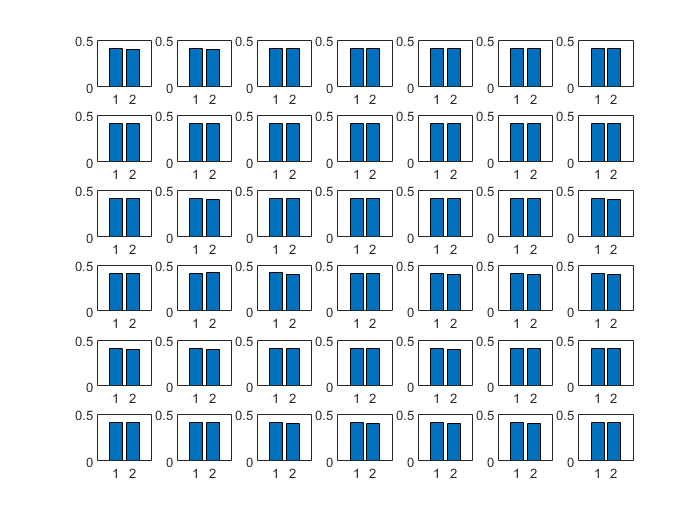

Error using subplot (line 317)
Illegal plot number.

DataR = rescale(Data); %rescale Data in order to have the same order of magnitude
indiciN = find(Response==0); %indexes that correspond to normal situations
indiciP = find(Response==1); %indexes that correspond to critic situations
DataRN = DataR(indiciN, :);  %rescaled data, only normal
DataRP = DataR(indiciP, :);  %rescaled data, only abnormal
for i=1:42
    a=[mean(DataRN(:,i)) mean(DataRP(:,i))];
    bar(a)
    subplot(6,7,i)
end

The barplot does not give us any information. We now take the entire vector of the differences.

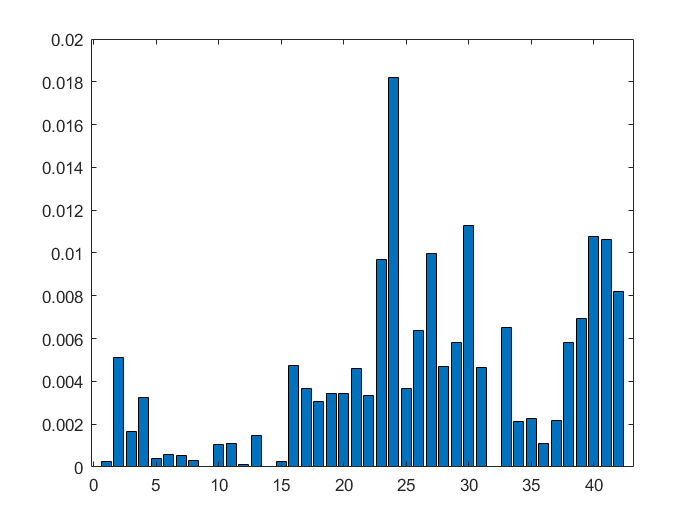

figure
DataDifference = abs(mean(DataRN) - mean(DataRP));
%massimo = max(DataDifference);
%minimo = min(DataDifference);
%DataDifference = (DataDifference - minimo) / (massimo - minimo);
bar(DataDifference)

The most marked difference is in the 24th feature, which is the ECSURPUS. We can also set a treshold and consider only the features whose difference is above a certain treshold.

For example:

indiciInteressanti = find(DataDifference > 0.006)

indiciInteressanti =     23    24    26    27    30    33    39    40    41    42


In order, we have log diff of VIX, Economic Surprise Index,  differences of: GTDEM10Y, GTDEM2Y, GTGBP2Y, GTITL2YR, USGG3M, USGG2YR, GT10, USGG30YR.

DataDifference(23) %difference in the log diff of VIX (NORMAL - ABNORMAL)

ans = 0.0097

DataDifference(24) %difference in the ECSURPUS (NORMAL - ABNORMAL)

ans = 0.0182

### **Normalization**

In the given algorithm for classification we computed the probability for the observations in the cross validation set and in the test set to belong to a normal distribution with mean and covariance matrix equal to the sample mean vector and the sample covariance matrix of the training set (made only by not anomalous data, so it is a sort of novelty detection). We try to normalize the data before taking this step.

%addpath 'C:\Users\margh\AppData\Roaming\MathWorks\MATLAB Add-Ons\Functions\Shapiro-Wilk and Shapiro-Francia normality tests'
for i=1:42
[H,pval,~] = swtest(Data(:,i),0.05)
end

H = logical
   1


pval = 3.4593e-12

H = logical
   1


pval = 1.1102e-16

H = logical
   1


pval = 5.5511e-16

H = logical
   1


pval = 0

H = logical
   1


pval = 9.1211e-06

H = logical
   1


pval = 0

H = logical
   1


pval = 9.8810e-15

H = logical
   1


pval = 3.0454e-07

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 4.3743e-14

H = logical
   1


pval = 1.1102e-16

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 1.1102e-16

H = logical
   1


pval = 0.0484

H = logical
   1


pval = 0

H = logical
   1


pval = 1.7611e-09

H = logical
   1


pval = 0

H = logical
   1


pval = 1.3826e-12

H = logical
   1


pval = 7.6787e-12

H = logical
   1


pval = 0

H = logical
   1


pval = 8.0629e-11

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 0

H = logical
   1


pval = 1.1215e-08

H = logical
   1


pval = 5.8802e-08

%credits
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                Copyright (c) 17 March 2009 by Ahmed Ben Saïda          %
%                 Department of Finance, IHEC Sousse - Tunisia           %
%                       Email: ahmedbensaida@yahoo.com                   %
%                    $ Revision 3.0 $ Date: 18 Juin 2014 $               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


The observations are not normally distributed if we look by single feature. 

#### Box-Cox transformation

DataBox=Data+abs(min(min(Data)))+0.00000001;
%we have some negative data and BOX COX works only for positive numbers

for i=1:42
    [DataBox(:,i),~] = boxcox(DataBox(:,i)); 
end

## Model 1 - Box Cox

We tried the same classificator based on the probability of belonging to a normal distribution with mean and covariance equal to the sample mean and the sample covariance matrix of the training set. This is an example of NOVELTY detection, since in the training set we don't have the outliers.

nObs = length(Response); % #data
nObsNorm = sum(Response == 0); % #normal data points
nObsAbNorm = nObs - nObsNorm; % #abnormal data points
nObsTrain = round(0.80*nObsNorm); % #length training set
nObsCVNorm = round(0.10*nObsNorm); % #length normal portion of CV set
nObsCVabNorm = round(nObsAbNorm/2); % #length abnormal portion of CV set
nObsTest_abNorm = nObsAbNorm - nObsCVabNorm; % #length abnormal portion of Train set

% Reshuffling the sample
idxPermutation = randperm(nObs);
XBox = DataBox(idxPermutation,:);
Response = Response(idxPermutation);

% dividing normal/abnormal
Xnormal = XBox(Response == 0,:);
Xabnormal = XBox(Response == 1,:);
Yabnormal = Response(Response == 1,:);

XTrain = Xnormal(1:nObsTrain,:);
XCV = [Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,:); Xabnormal(1:nObsCVabNorm,:)];
XTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,:); Xabnormal(nObsCVabNorm+1:end,:)];

yCV = zeros(length(XCV),1);
yCV(end-nObsCVabNorm+1:end) = Yabnormal(1:nObsCVabNorm);
yTest = zeros(length(XTest),1);
yTest(end-nObsTest_abNorm+1:end) = Yabnormal(nObsCVabNorm+1:end);

sigma = cov(XTrain);
sigma = 0.5*(sigma+sigma'); % ensures symmetry
mu = mean(XTrain);

p = mvnpdf(XCV,mu,sigma); % compute the probability density function for each example

[bestEpsilon, bestF1] = OptimThreshold(yCV, p) % find the optimal epsilon

Unrecognized function or variable 'OptimThreshold'.

p = mvnpdf(XTest,mu,sigma);
predictions = p < bestEpsilon;

Unrecognized function or variable 'bestEpsilon'.

tp = sum((predictions == 1) & (yTest == 1))
fp = sum((predictions == 1) & (yTest == 0))
fn = sum((predictions == 0) & (yTest == 1))
prec = tp / (tp + fp)
rec = tp / (tp + fn)
F1 = 2 * prec * rec / (prec + rec)

The values of F1 and of the recall are good and there aren't many false negative, but there are some false positive (that correspond to a situation which is not a crisis classified as a crisis). We do not want this since this may lead to a loss (in a situation of presumed crisis one could decide to sell its actions and so on...). 

## Model 2 - Box Cox + correction for the anomally good situations

We implement a similar strategy but we try to consider the fact that not only the risk off situations have a small probability of belonging to the normal distribution with the same mean and covariance of the training set, but also the situations in which the values indicate a big improvement. 

With PCA we saw that the ECSURPUS had a good impact on the variance of the dataset and in particular, roughly speaking, a big score on the first principal component meant that in general the observation was NOT anomalous, even if it was distant from the mean. 

A similar reasoning may be done for the GTITL2YR referring to the second PC.

We try to set two tresholds both for the ECSURPUS and for the GTITL2YR beyond which the observation, even if it has a small probability of belonging to the normal distribution identified in the training set, is classified as normal. 

We also know that the mean of the VIX of the abnormal observations is pretty different from the one of the normal observations, and in particular the VIX is in mean higher for the "risk off" situations. This is coherent with the financial aspects of this analysis: the VIX is the volatility index and is also known as the 'fear' index, because it denotes the level of fear and stress present on the market. 

We set another treshold for the VIX, but this time the obserbation is not classified as abnormal if its log difference of the VIX is lower than a given quantity.

After some trials, we decided to eliminate GTITL2YR since the computational time was too much if we did all the four  nested loops.


p = mvnpdf(XCV,mu,sigma);
GT2= [Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,33); Xabnormal(1:nObsCVabNorm,33)];
ECSID=[Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,24); Xabnormal(1:nObsCVabNorm,24)];
VIXID=[Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,23); Xabnormal(1:nObsCVabNorm,23)];
minp=min(p);
maxp=max(p);
stepp= (maxp - minp)/1000;
maxECSID=max(DataBox(:,24));
minECSID=min(DataBox(:,24));
maxGT2=max(DataBox(:,33));
minGT2=min(DataBox(:,33));
minVIX = min(DataBox(:,23));
maxVIX = max(DataBox(:,23));
stepE=(maxECSID-minECSID)/100;
stepG=(maxGT2-minGT2)/100;
stepV = (maxVIX - minVIX)/100;
bestEpsilon = 0;
bestF1 = 0;
bestRecall = 0;
bestPrecision = 0;
bestGT2treshold = maxECSID;
bestECSIDtreshold=maxGT2;
bestVIXtreshold = minVIX;

for epsilon=minp:stepp:maxp
    for j= minECSID:stepE:maxECSID
       % for k=minGT2:stepG:maxGT2
            for l = minVIX:stepV:maxVIX
           predictions = (p < epsilon & ECSID < j & VIXID > l);   %& GT2< k
    tp = sum((predictions == 1) & (yCV == 1));
    fp = sum((predictions == 1) & (yCV == 0));
    fn = sum((predictions == 0) & (yCV == 1));
    prec = tp / (tp + fp);
    rec = tp / (tp + fn);
    F1 = 2 * prec * rec / (prec + rec);

    if F1 > bestF1
        bestF1 = F1;
        %bestGT2treshold = k;
        bestECSIDtreshold=j;
        bestVIXtreshold = l;
        bestRecall=rec;
        bestPrecision = prec;
        bestEpsilon=epsilon;
    end
          
         end
      %end
    end
end
bestF1

bestF1 = 0.8000

bestRecall

bestRecall = 0.9412

bestPrecision

bestPrecision = 0.6957

p = mvnpdf(XTest,mu,sigma);
ECSIDTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,24); Xabnormal(nObsCVabNorm+1:end,24)];

GT2Test = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,33); Xabnormal(nObsCVabNorm+1:end,33)];
VIXTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,23); Xabnormal(nObsCVabNorm+1:end,23)];

predictions =( p < bestEpsilon & ECSIDTest < bestECSIDtreshold & VIXTest > bestVIXtreshold); % & GT2Test < bestGT2treshold
tp = sum((predictions == 1) & (yTest == 1))

tp = 107

fp = sum((predictions == 1) & (yTest == 0))

fp = 50

fn = sum((predictions == 0) & (yTest == 1))

fn = 11

prec = tp / (tp + fp)

prec = 0.6815

rec = tp / (tp + fn)

rec = 0.9068

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7782

We expected that the number of false positive would decrease more, but in the end we are satisfied with this model. The recall and the precision have not the highest values, but we have only 3 more not detected crisis versus 11 less normal periods classified as crisis.

## Model 3 - Approach with not normal Data but with Mahalanobis distance

In the previous models we used the probability of belonging to a normal distribution, now instead we do NOT normalize the data (we use the same stationary dataset of the beginning with diff and log diff) but we classify the points in the CV set and in the Test set as anomalous if their Mahalanobis distance from the distribution of the training set is bigger than a treshold. We use the function OptimDistance, which is basically the same of OptimTreshold but in this case we classify as risk off the observations whose distance is BIGGER (not SMALLER) than the treshold.

This distance is zero for *P* at the mean of *D, *a certain probability distrubution, and grows as *P* moves away from the mean along each principal component axis. If each of these axes is re-scaled to have unit variance, then the Mahalanobis distance corresponds to standard Euclidean distance in the transformed space. The Mahalanobis distance is thus unitless, scale-invariant, and takes into account the correlations of the dataset. That's why we don't need to rescale or normalize the variables.

%%from Zenti code, in case we overlapped some names of the variables
% % Always positive variables => log-differences (log-returns)
Indices_Currencies = [XAUBGNL BDIY CRY Cl1 DXY EMUSTRUU GBP JPY LF94TRUU LF98TRUU LG30TRUU LMBITR LP01TREU...
       LUACTRUU LUMSTRUU MXBR MXCN MXEU MXIN MXJP MXRU MXUS VIX];

% Possibly negative variables => first differences
InterestRates = [EONIA GTDEM10Y GTDEM2Y GTDEM30Y GTGBP20Y GTGBP2Y GTGBP30Y...
    GTITL10YR GTITL2YR GTITL30YR GTJPY10YR GTJPY2YR GTJPY30YR US0001M USGG3M USGG2YR GT10 USGG30YR];

Data = [diff(log(Indices_Currencies)) ECSURPUS(2:end) diff(InterestRates)]; % make stationary
Response = Y(2:end); % we lose one observation (the first)
%%end of Zenti code

%same division into the three sets
nObs = length(Response); % #data
nObsNorm = sum(Response == 0); % #normal data points
nObsAbNorm = nObs - nObsNorm; % #abnormal data points
nObsTrain = round(0.80*nObsNorm); % #length training set
nObsCVNorm = round(0.10*nObsNorm); % #length normal portion of CV set
nObsCVabNorm = round(nObsAbNorm/2); % #length abnormal portion of CV set
nObsTest_abNorm = nObsAbNorm - nObsCVabNorm; % #length abnormal portion of Train set

% Reshuffling the sample
idxPermutation = randperm(nObs);
X = Data(idxPermutation,:);
Response = Response(idxPermutation);

% dividing normal/abnormal
Xnormal = X(Response == 0,:);
Xabnormal = X(Response == 1,:);
Yabnormal = Response(Response == 1,:);
%si potrebbe mettere abnormal già in training
XTrain = Xnormal(1:nObsTrain,:);
XCV = [Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,:); Xabnormal(1:nObsCVabNorm,:)];
XTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,:); Xabnormal(nObsCVabNorm+1:end,:)];
yCV = zeros(length(XCV),1);
yCV(end-nObsCVabNorm+1:end) = Yabnormal(1:nObsCVabNorm);
yTest = zeros(length(XTest),1);
yTest(end-nObsTest_abNorm+1:end) = Yabnormal(nObsCVabNorm+1:end);

%I compute for every point of the CV set its Mahalanobis distance from the
%center of the distribution
% I choose the best treshold with the function OptimTreshold, optimizing
% the F1 statistic
% under this treshold I classify the point as normal
% over this treshold I classify the point as abnormal

d = mahal(XCV, XTrain);

[bestd, bestF1] = OptimDistance(yCV, d) % find the optimal epsilon

bestd = 36.2623

bestF1 = 0.7939

%testing
d = mahal(XTest,XTrain);
predictions = d > bestd;
tp = sum((predictions == 1) & (yTest == 1))

tp = 100

fp = sum((predictions == 1) & (yTest == 0))

fp = 39

fn = sum((predictions == 0) & (yTest == 1))

fn = 18

prec = tp / (tp + fp)

prec = 0.7194

rec = tp / (tp + fn)

rec = 0.8475

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7782

## Model 4 - Approach with not normal Data but with Mahalanobis distance + correction for the anomally good situations

We did the same as in model 2.

d = mahal(XCV,XTrain);
GT2= [Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,33); Xabnormal(1:nObsCVabNorm,33)];
ECSID=[Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,24); Xabnormal(1:nObsCVabNorm,24)];
VIXID=[Xnormal(nObsTrain+1:nObsTrain+1+nObsCVNorm,23); Xabnormal(1:nObsCVabNorm,23)];

mind=min(d);
maxd=max(d);
stepd= (maxd - mind)/1000;
maxECSID=max(Data(:,24));
minECSID=min(Data(:,24));
maxGT2=max(Data(:,33));
minGT2=min(Data(:,33));
minVIX = min(Data(:,23));
maxVIX = max(Data(:,23));
stepE=(maxECSID-minECSID)/100;
stepG=(maxGT2-minGT2)/100;
stepVIX = (maxVIX - minVIX)/100;
bestPrecision = 0;
bestRecall = 0;
bestEpsilon = 0;
bestF1 = 0;
bestVIXtreshold = maxVIX;
bestECSIDtreshold = minECSID;
for distance=mind:stepd:maxd
    for j= minECSID:stepE:maxECSID
        %for k=minGT2:stepG:maxGT2
            for l=minVIX:stepVIX:maxVIX
           predictions = (d > distance & ECSID < j & VIXID > l); %& GT2< k
    tp = sum((predictions == 1) & (yCV == 1));
    fp = sum((predictions == 1) & (yCV == 0));
    fn = sum((predictions == 0) & (yCV == 1));
    prec = tp / (tp + fp);
    rec = tp / (tp + fn);
    F1 = 2 * prec * rec / (prec + rec);

    if F1 > bestF1
        bestF1 = F1;
        %bestGT2treshold = k;
        bestECSIDtreshold=j;
        bestVIXtreshold=l;
        bestRecall=rec;
        bestPrecision = prec;
        bestDistance=distance;
    end
            end
          
    %end
end
end
bestF1

bestF1 = 0.7969

bestRecall

bestRecall = 0.8739

bestPrecision

bestPrecision = 0.7324

%bestGT2treshold
bestECSIDtreshold

bestECSIDtreshold = 0.5390

bestVIXtreshold

bestVIXtreshold = -0.3941

%testing
d = mahal(XTest,XTrain);
ECSIDTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,24); Xabnormal(nObsCVabNorm+1:end,24)];
GT2Test = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,33); Xabnormal(nObsCVabNorm+1:end,33)];
VIXTest = [Xnormal(nObsTrain+1+nObsCVNorm+1:end,23); Xabnormal(nObsCVabNorm+1:end,23)];

predictions = (d > bestDistance & ECSIDTest < bestECSIDtreshold & VIXTest > bestVIXtreshold); %& GT2Test <bestGT2treshold
tp = sum((predictions == 1) & (yTest == 1))

tp = 99

fp = sum((predictions == 1) & (yTest == 0))

fp = 33

fn = sum((predictions == 0) & (yTest == 1))

fn = 19

prec = tp / (tp + fp)

prec = 0.7500

rec = tp / (tp + fn)

rec = 0.8390

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7920

## Model 5 - **UNSUPERVISED CLASSIFICATION**

**Hierarchical clustering on the whole original dataset**

We have tried an approach with hierachical clustering based on different distance metrics and with the original dataset collected in the matrix DataNS (we did not proceed in making the first differences or the log differences). The idea is to start with each observation in its own cluster and then to combine the two closest clusters until we have one single cluster with all the observations. 

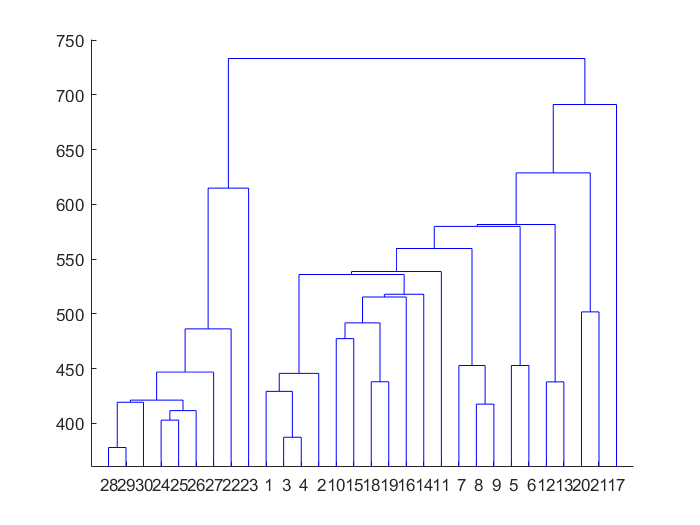

% single linkage
LSE = linkage(DataNS,'single','euclidean');
LSM = linkage(DataNS,'single','mahalanobis');
LSC = linkage(DataNS,'single','chebychev');

dendrogram(LSE);

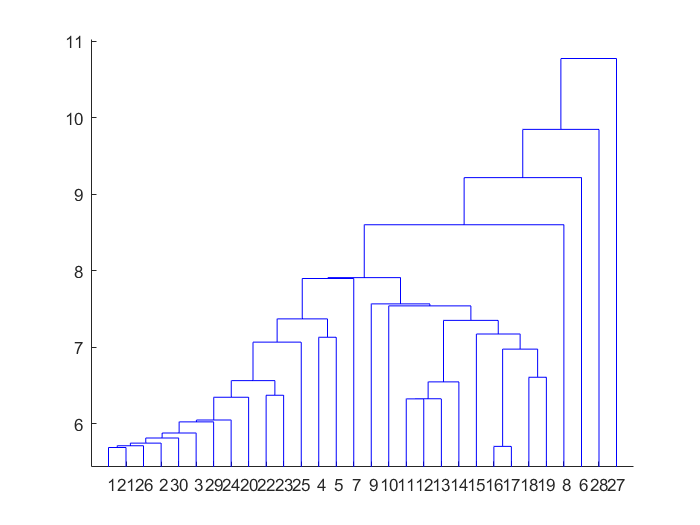

dendrogram(LSM);

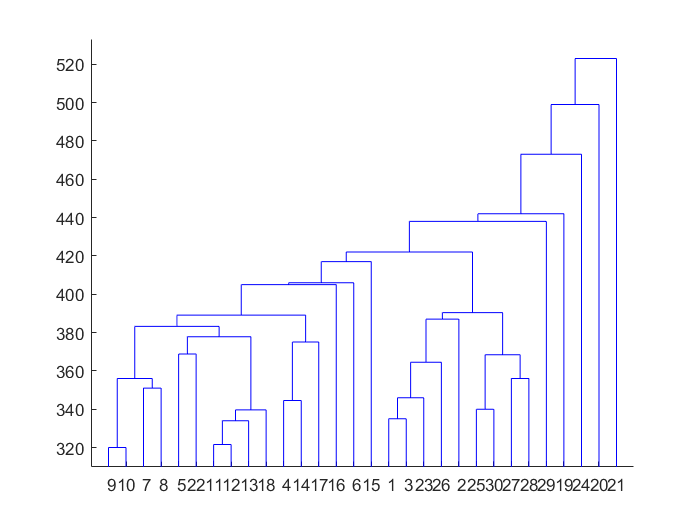

dendrogram(LSC);


TSE = cluster(LSE,'maxclust',2);
TSM = cluster(LSM,'maxclust',2);
TSC = cluster(LSC,'maxclust',2)

TSC =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


**Comparison with the vector Y**

nAbnormal = length(Response(Response==1))

nAbnormal = 237

nNormal = length(Response(Response==0))

nNormal = 873

nclass1Euclidean= length(TSE(TSE==1))

nclass1Euclidean = 656

nclass2Euclidean = length(TSE(TSE==2))

nclass2Euclidean = 455

nclass1Mahalanobis = length(TSM(TSM==1))

nclass1Mahalanobis = 1

nclass2Mahalanobis = length(TSM(TSM==2))

nclass2Mahalanobis = 1110

%clearly mahalanobis distance with this link does not work (only one
%component in a class) - model to be discarded
nclass1Chebychev = length(TSC(TSC==1))

nclass1Chebychev = 4

nclass2Chebychev = length(TSC(TSC==2))

nclass2Chebychev = 1107

% the same goes for chebychev , only 4 observation in a class


% model to be discarded
%let's see if with Euclidean distance the labels are comparable
%also the dendrogram seems the most promising one
%l1 norm
TSE=TSE-1;
l1norm=sum(abs(TSE-Y))

l1norm = 498

%clearly it does not make sense

We were not satisfied with the outcome and especially with the comparison with the real labels.

We have tried with different algorithms for computing the distance between clusters

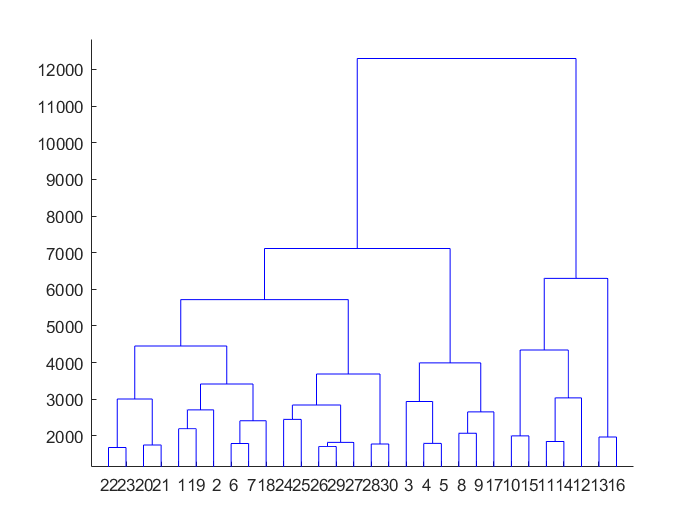

% scomplete linkage
LCE = linkage(DataNS,'complete','euclidean');
LCM = linkage(DataNS,'complete','mahalanobis');
LCC = linkage(DataNS,'complete','chebychev');

dendrogram(LCE);

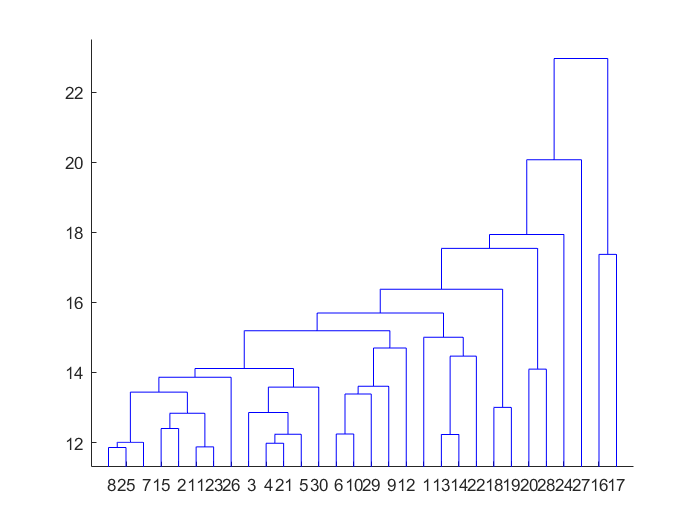

dendrogram(LCM);

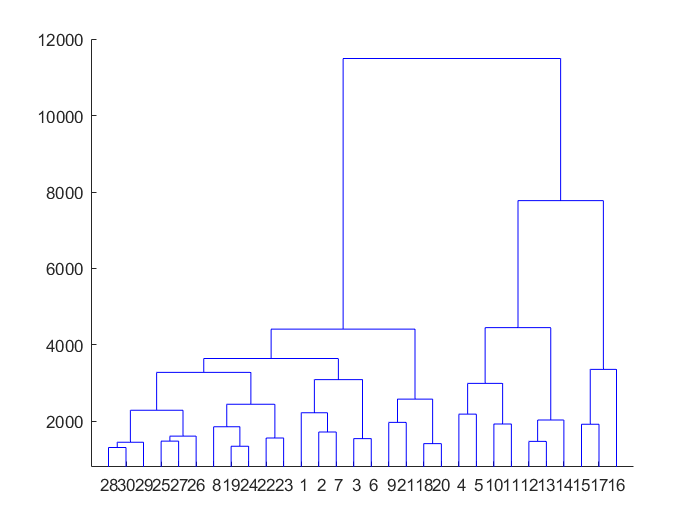

dendrogram(LCC)

TCE = cluster(LCE,'maxclust',2);
TCM = cluster(LCM,'maxclust',2);
TCC = cluster(LCC,'maxclust',2);

**Comparison with the vector Y**

nAbnormal = length(Response(Response==1))

nAbnormal = 237

nNormal = length(Response(Response==0))

nNormal = 873

nclass1Euclidean= length(TCE(TCE==1))

nclass1Euclidean = 70

nclass2Euclidean = length(TCE(TCE==2))

nclass2Euclidean = 1041

nclass1Mahalanobis = length(TCM(TCM==1))

nclass1Mahalanobis = 7

nclass2Mahalanobis = length(TCM(TCM==2))

nclass2Mahalanobis = 1104

nclass1Chebychev = length(TCC(TCC==1))

nclass1Chebychev = 959

nclass2Chebychev = length(TCC(TCC==2))

nclass2Chebychev = 152

Therefore we have to discard for the same reason of the single linkage, also the complete algorithm since we have in the two groups a number of units too distant from the number of units in the original two groups.

## Model 6 - sort of KNN

The idea is to compute first the mean of the features within the two groups. Then after having computed the distances between each unit and these two mean vectors, see whether the unit is classified into the group with the closer mean. We have decided to try with euclidean distance.

Data0= DataNSY(Y==0, :);     
Data1 = DataNSY(Y==1, :);

M0 = mean(Data0);
M1 = mean(Data1);

tp=0; tn=0; fp=0; fn=0;
for i=1:1111
    d0=norm(DataNSY(i,1:42)- M0(1:42));
    d1=norm(DataNSY(i,1:42)- M1(1:42));
    if (d1<d0 & DataNSY(i,43)==1)
        tp=tp+1;
    end
    if (d1<d0 & DataNSY(i,43)==0)
        fp=fp+1;
    end
    if (d0<d1 & DataNSY(i,43)==0)
        tn=tn+1;
    end
    if (d0<d1 & DataNSY(i,43)==1)
        fn=fn+1;
    end
end

tp

tp = 159

tn

tn = 553

fp

fp = 321

fn

fn = 78

As we can notice, we have to discard this approach since we have a high number of fp and fn, units that actually belong to a group different from that expected by this 'algorithm'.

## Model 7 - KNN for anomaly detection

We used the stationary Data but we performed anomaly detection. 

For this model see the file "KNNanomaly.ipynb"

The idea is to compute the k nearest neighbors for every observation, then to plot the mean of k-distances of each observation and to visually determine a cutoff over which the observations are classified as anomalies. We set k=3 and cutoff=0.4

outlier_indexes=[ 50,   64,   65,   86,   87,   92,   95,  395,  396,  417,  418, 425,  426,  452,  453,  454,  455,  456,  457,  458,  459,  460, 461,  462,  464,  465,  467,  468,  470,  471,  472,  473,  476, 489,  581,  602,  611,  615,  619,  620,  625,  646,  649,  652, 700,  797,  813,  957,  958, 1049, 1050, 1051, 1052, 1056, 1058] + 1;

v=zeros(length(Response),1);
for i=1:55
    j=outlier_indexes(i);
    v(j)=1;
end
l1norm=sum(abs(v-Response))
%the l1 norm is better than the case of hierarchical clustering but it is
%still consistent

l1norm = 276

%there are many false negatives 

outliers = [   0,    1,    3,    7,    8,   10,   14,   15,   17,   19,   34, ...
          36,   45,   49,   50,   58,   61,   62,   64,   65,   66,   68, ...
          75,   76,   85,   86,   87,   88,   91,   92,   93,   95,   98, ...
         101,  103,  107,  111,  129,  130,  131,  136,  139,  142,  144, ...
         146,  161,  164,  178,  180,  184,  186,  187,  188,  193,  199, ...
         200,  201,  205,  215,  224,  307,  333,  334,  370,  373,  386, ...
         394,  395,  396,  397,  398,  399,  400,  402,  403,  404,  408, ...
         410,  412,  413,  414,  415,  416,  417,  418,  420,  423,  424, ...
         425,  426,  430,  431,  433,  434,  437,  441,  442,  443,  450, ...
         451,  452,  453,  454,  455,  456,  457,  458,  459,  460,  461, ...
         462,  463,  464,  465,  466,  467,  468,  469,  470,  471,  472, ...
         473,  475,  476,  477,  478,  480,  483,  485,  487,  488,  489, ...
         490,  492,  498,  512,  537,  539,  563,  564,  566,  567,  572, ...
         574,  575,  576,  577,  578,  580,  581,  585,  586,  589,  596, ... 
         598,  599,  600,  601,  602,  606,  608,  610,  611,  614,  615, ...
         617,  618,  619,  620,  621,  623,  624,  625,  628,  631,  632, ... 
         633,  634,  637,  644,  646,  649,  650,  651,  652,  653,  654, ...
         658,  659,  673,  700,  701,  777,  778,  783,  789,  791,  797, ...
         803,  805,  807,  813,  841,  857,  868,  875,  877,  900,  941, ...
         957,  958,  975,  983, 1019, 1024, 1029, 1044, 1048, 1049, 1050, ...
        1051, 1052, 1053, 1055, 1056, 1057, 1058, 1064, 1065, 1085] + 1;

vConfronto = zeros(length(Response), 1);
for i = 1:length(outliers)
    j = outliers(i);
    vConfronto(j) = 1;
end

sum(abs(Response - vConfronto))

ans = 379

tp = sum((vConfronto == 1) & (Response == 1))

tp = 44

fp = sum((vConfronto == 1) & (Response == 0))

fp = 186

fn = sum((vConfronto == 0) & (Response == 1))

fn = 193

prec = tp / (tp + fp)

prec = 0.1913

rec = tp / (tp + fn)

rec = 0.1857

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.1884

As we can see the indicators such as the number of false negatives and false positives, the recall and the F1 are not good, so we decided to discard this "naive" model. 

## Model 8 - Gaussian Copulas

**The key point on Copulas**

Copulas are functions that describe dependencies among variables, and provide a way to create distributions that model correlated multivariate data.

The idea is that you can construct a multivariate distribution by specifying marginal univariate distributions, and then choose a Copula to provide a correlation structure between variables. Therefore a factorization of marginals and correlation, which are thus independently modeled, is carried out, with great advantages from the point of view of the realistic representation of the data.

**TRAINING**

[nObs, nFeatures] = size(XTrain);
uTrain = zeros(nObs, nFeatures);

% Extracting the sample of uniform RV from CDF
for i = 1:nFeatures
    uTrain(:,i) = ksdensity(XTrain(:,i), XTrain(:,i), 'function', 'cdf');
end

% Fit a Gaussian copula
RhoHat = copulafit('Gaussian', uTrain);  

**CROSS-VALIDATION FOR HIGHER PARAMETERS FINE-TUNING**

[nObs, nFeatures] = size(XCV);
uCV = zeros(nObs, nFeatures);

% Extracting the sample of uniform RV from CDF 
for i = 1:nFeatures
    uCV(:,i) = ksdensity(XCV(:,i), XCV(:,i), 'function', 'cdf');
end

% Probability densities on CV set
p = copulapdf('Gaussian',uCV,RhoHat);

% Estimating optimal threshold epsilon with the function OptimTreshold
[bestEpsilon, bestF1] = OptimThreshold(yCV, p)

bestEpsilon = 9.8810e+32

bestF1 = 0.7262

**TESTING**

[nObs, nFeatures] = size(XTest);
uTest = zeros(nObs, nFeatures);

% Extracting the sample of uniform RV from CDF 
for i = 1:nFeatures
    uTest(:,i) = ksdensity(XTest(:,i), XTest(:,i), 'function', 'cdf');
end

% Probability densities on Test set
p = copulapdf('Gaussian',uTest,RhoHat);

% Predictions and classification
predictions = p < bestEpsilon;
tp = sum((predictions == 1) & (yTest == 1))

tp = 118

fp = sum((predictions == 1) & (yTest == 0))

fp = 87


%real negatives -> real normal situations
sum(1-yTest)

ans = 87

%real positives -> real "risk off" situations

fn = sum((predictions == 0) & (yTest == 1))

fn = 0

prec = tp / (tp + fp)

prec = 0.5756

rec = tp / (tp + fn)

rec = 1

F1 = 2 * prec * rec / (prec + rec)

F1 = 0.7307

The numerical results are good, but we have to carefully understand their meaning. The false positives represent all the normal situations. We met a "trivial" classifier: every  normal observation in the test set is classified as 1, as abnormal. 

For this issue we discarded this model. 

In the end we can see that the best model we have is the second. This offers the best trade off between the risk of not detecting a crisis and the risk of classifying as crisis a normal period. 